初期設定

%%%磁石の大きさ（単位：mm ）%%%
x1=0.0;
x2=0.04;
x3=0.06;
x4=0.1;
y1=0.0;
y2=0.020;
y3=0.080;
y4=0.1;
z1=0; 
z2=0.002;
z3=0.004;   

%settings for truncation
En=0.01;
%%%分割幅 width of measurements n and how much youre making nmag%%%
n=0.002;
nmag=0.001;
M=[0;0;1];
%%%分割数+1%%%
nx=round((abs(x4-x1)/n)+1);
ny=round((abs(y4-y1)/n)+1);
nz=1;
nxmag=round((abs(x3-x2)/n)+1);
nymag=round((abs(y3-y2)/n)+1);
nzmag=1;

%%%直方体領域の頂点の座標%%%
Ncx=linspace(x2+nmag/2,x3+nmag/2,nxmag);      %頂点のX座標
Ncy=linspace(y2+nmag/2,y3+nmag/2,nymag);      %頂点のY座標
Ncz=[z1,z2];                 %頂点のZ座標

%%%直方体領域の頂点の中間点の座標 x,yのみ%%%
Ncxx=linspace(x1+n/2,x4-n/2,nx-1);
Ncyy=linspace(y1+n/2,y4-n/2,ny-1);
Nczz=repmat(z2,nx,ny);       
%magpart
Ncxmag=linspace(x2+nmag/2,x3-nmag/2,nxmag-1);
Ncymag=linspace(y2+nmag/2,y3-nmag/2,nymag-1);
Nczmag=repmat(z2,nxmag-1,nymag-1)

Nczmag =     0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020
    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020
    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020
    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.00


%%%各方向の測定回数%%%
Nx=nx-1;
Ny=ny-1;
Nz=1;


%Nmzのみユーザーが設定する%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%測定する範囲の(0点からの)大きさ。
% せんさの中央の座標分）で割れる大きさにする%%%%
Wnx=(x4-x1)/Nx

Wnx = 0.0020

Wny=(y4-y1)/Ny

Wny = 0.0020

Nmx=Wnx*Nx-Wnx/2;
Nmy=Wny*Ny-Wny/2;
Nmz=z2;    % Zのみ測定する座標そのものなことに注意


%%%測定点数合計%%%
Nn=Nx*Ny

Nn = 2500

%Nm is measurement area
Nm=zeros(3,Nn);
Ni=1;Nj=1;%反復計算用
for nmy=Wny/2:Wny:Nmy   %Nmに座標を入れていく計算

    for  nmx=Wnx/2:Wnx:Nmx
        Nm(:,Ni)=[nmx,nmy,Nmz];
        Ni=Ni+1;
    end
    
    Nj=Nj+1;
end
Nm

Nm =     0.0010    0.0030    0.0050    0.0070    0.0090    0.0110    0.0130    0.0150    0.0170    0.0190    0.0210    0.0230    0.0250    0.0270    0.0290    0.0310    0.0330    0.0350    0.0370    0.0390    0.0410    0.0430    0.0450    0.0470    0.0490    0.0510    0.0530    0.0550    0.0570    0.0590    0.0610    0.0630    0.0650    0.0670    0.0690    0.0710    0.0730    0.0750    0.0770    0.0790    0.0810    0.0830    0.0850    0.0870    0.0890    0.0910    0.0930    0.0950    0.0970    0.0990
    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    

磁化ベクトル推定のシミュレーション（B＝AMの順方向を行う）

Aを計算し，Mを与えてBを算出する．

%I=∭vΔ(1/r)dv とその組み合わせの行列であるAを求める%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
 
Nc=round((nx-1)*(ny-1))

Nc = 2500

Ncmag=round((nxmag-1)*(nymag-1))

Ncmag = 300

A=zeros(3*Nn,3*Ncmag);             %電流密度要素数
pp=0;cc=0;                      %Aに計算する時の計算用
Aa=zeros(3);   %一測定点と一要素（最終敵には合算されてAになる）
Ixx=0;Iyy=0;Izz=0;           %Iをx,y,z方向に分解したもの
Ixy=0;Iyz=0;Ixz=0; 

for cy=0:nymag-2                   %直方体頂点の座標(Ncy)の指定ny-2
    for cx=0:nxmag-2               %直方体頂点の座標(Ncx)の指定nx-2　（計算頂点の始点をずらすためのcy,cz（Zは移動しないのでいらない））
 
        pp=0;
        for p=1:Nc                 %測定点数Nn 
                for k=1:2           %頂点のz方向への移動
                    for j=1:2       %頂点のy方向への移動
                        for i=1:2   %頂点のx方向への移動

                          R=sqrt(((Nm(1,p)-Ncx(i+cx))^2)+((Nm(2,p)-Ncy(j+cy))^2)+((Nm(3,p)-Ncz(k))^2)); %直方体領域の頂点と測定点との距離
    
                          Ixxp=((-1)^(i+j+k))*(-(atan(((Nm(2,p)-Ncy(j+cy))*(Nm(3,p)-Ncz(k)))/((Nm(1,p)-Ncx(i+cx))*R))));
            
                          Ixyp=((-1)^(i+j+k))*(log(R+(Nm(3,p)-Ncz(k))));
                       
                          Ixzp=((-1)^(i+j+k))*(log(R+(Nm(2,p)-Ncy(j+cy))));
                          
                          Iyyp=((-1)^(i+j+k))*(-(atan(((Nm(1,p)-Ncx(i+cx))*(Nm(3,p)-Ncz(k)))/((Nm(2,p)-Ncy(j+cy))*R))));
                          
                          Iyzp=((-1)^(i+j+k))*(log(R+(Nm(1,p)-Ncx(i+cx))));
                          
                          Izzp=((-1)^(i+j+k))*(-(atan(((Nm(1,p)-Ncx(i+cx))*(Nm(2,p)-Ncy(j+cy)))/((Nm(3,p)-Ncz(k))*R))));
                          
                          
                          Ixx=Ixx+Ixxp;
                          Ixy=Ixy+Ixyp;
                          Ixz=Ixz+Ixzp;
                          Iyy=Iyy+Iyyp;
                          Iyz=Iyz+Iyzp;
                          Izz=Izz+Izzp;
                          
                        end
                    end
                end
                
               %NaNの対処%%%%%%%%%%%%%%%%
               if isnan(Ixx)
                     Ixxp=0;
               end      
               if isnan(Iyy)
                     Iyyp=0;
               end      
               if isnan(Izz)
                     Izzp=0;
               end
               if isnan(Ixy)
                     Ixyp=0;
               end      
               if isnan(Ixz)
                     Ixzp=0;
               end      
               if isnan(Iyz)
                     Iyzp=0;
               end

               %%%%%%%%%%%%%%%%%%%%%%%%%%%
               
               Aa=(-(1/(4*pi)))*[Ixx,Ixy,Ixz;
                               Ixy,Iyy,Iyz;
                               Ixz,Iyz,Izz];


               A(3*pp+1,3*cc+1)=Aa(1,1);
               A(3*pp+1,3*cc+2)=Aa(2,1);
               A(3*pp+1,3*cc+3)=Aa(3,1);
               
               A(3*pp+2,3*cc+1)=Aa(1,2);
               A(3*pp+2,3*cc+2)=Aa(2,2);
               A(3*pp+2,3*cc+3)=Aa(3,2);
               
               A(3*pp+3,3*cc+1)=Aa(1,3);
               A(3*pp+3,3*cc+2)=Aa(2,3);
               A(3*pp+3,3*cc+3)=Aa(3,3);
               
               Ixx=0;            %ループ毎のIの初期化
               Iyy=0;
               Izz=0;
               Ixy=0;
               Iyz=0;
               Ixz=0;
                
               pp=pp+1;
        end
         cc=cc+1;
    end
end

A

A =     0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000
    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0

Msim=repmat([0;0;1],Ncmag,1);
Bsim=A*Msim

Bsim =    -0.0000
   -0.0000
   -0.0006
   -0.0000
   -0.0000
   -0.0007
   -0.0000
   -0.0000
   -0.0008
   -0.0000


Bsimx=zeros(nymag-1,nxmag-1);    %x方向電流密度
Bsimy=zeros(nymag-1,nxmag-1);    %y方向
Bsimz=zeros(nymag-1,nxmag-1);    %z方向
mmx=1;mmy=1;            %計算用変数
for jj=1:Nn

    if mmx < nx-1
        Bx(mmy,mmx)=Bsim(3*(jj)-2);
        By(mmy,mmx)=Bsim(3*(jj)-1);
        Bz(mmy,mmx)=Bsim(3*(jj));
        mmx=mmx+1;

    elseif mmx==nx-1
        Bx(mmy,mmx)=Bsim(3*(jj)-2);
        By(mmy,mmx)=Bsim(3*(jj)-1);
        Bz(mmy,mmx)=Bsim(3*(jj));
        mmx=1;
       mmy=mmy+1;
    end
end


Bx

Bx =    -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    

By

By =    -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0002   -0.0002   -0.0002   -0.0002   -0.0003   -0.0003   -0.0003   -0.0003   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0003   -0.0003   -0.0003   -0.0003   -0.0002   -0.0002   -0.0002   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0002   -0.0002   -0.0002   -0.0003   -0.0003   -0.0003   -0.0004   -0.0004   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0004   -0.0004   -0.0004   -0.0003   -0.0003   -0.0002   -0.0002   -0.0002   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -

Bz

Bz =    -0.0006   -0.0007   -0.0008   -0.0008   -0.0009   -0.0010   -0.0010   -0.0011   -0.0012   -0.0013   -0.0015   -0.0016   -0.0017   -0.0019   -0.0021   -0.0023   -0.0024   -0.0026   -0.0028   -0.0030   -0.0032   -0.0034   -0.0035   -0.0036   -0.0036   -0.0037   -0.0036   -0.0036   -0.0034   -0.0033   -0.0031   -0.0029   -0.0027   -0.0025   -0.0023   -0.0022   -0.0020   -0.0018   -0.0017   -0.0015   -0.0014   -0.0013   -0.0012   -0.0011   -0.0010   -0.0009   -0.0008   -0.0008   -0.0007   -0.0007
   -0.0007   -0.0007   -0.0008   -0.0009   -0.0009   -0.0010   -0.0011   -0.0012   -0.0013   -0.0015   -0.0016   -0.0018   -0.0020   -0.0022   -0.0024   -0.0026   -0.0029   -0.0031   -0.0034   -0.0036   -0.0039   -0.0041   -0.0043   -0.0044   -0.0045   -0.0045   -0.0045   -0.0044   -0.0042   -0.0040   -0.0038   -0.0035   -0.0032   -0.0030   -0.0027   -0.0025   -0.0023   -0.0021   -0.0019   -0.0017   -0.0015   -0.0014   -0.0013   -0.0012   -0.0011   -0.0010   -0.0009   -0.0008   -0.0008   -

算出したBを表示する

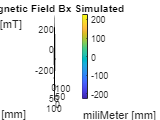


surf(Ncxx*1000,Ncyy*1000,Bx*1000)
set(gca,'YDir','reverse')   %Y軸方向反転処理
% xlim([0 Nx+1])
% ylim([0 Ny+1])
b=(["Magnetic Field Bx Simulated "]);
title(b)
zlabel('miliTesla [mT]', 'FontSize',10) 
xlabel('miliMeter [mm]', 'FontSize',10) 
ylabel('miliMeter [mm]', 'FontSize',10)
colorbar

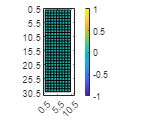


%2D分布
surf(Bsimx)
set(gca,'YDir','reverse')
axis equal
grid off
box on
xlim([0.5 nxmag+0.5])
ylim([0.5 nymag+0.5])
xticks(0.5:5:nxmag+1)
yticks(0.5:5:nymag+1)
view([0 90.0])
colorbar

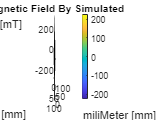


%Byの表示%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%3D分布
surf(Ncxx*1000,Ncyy*1000,By*1000)
set(gca,'YDir','reverse')
b=(["Magnetic Field By Simulated "]);
title(b)
zlabel('miliTesla [mT]', 'FontSize',10) 
xlabel('miliMeter [mm]', 'FontSize',10) 
ylabel('miliMeter [mm]', 'FontSize',10)
colorbar


%2D分布
surf(Bsimy)
set(gca,'YDir','reverse')
colorbar
axis equal
grid off
box on
xlim([0.5 nxmag+0.5])
ylim([0.5 nymag+0.5])
xticks(0.5:5:nxmag+1)
yticks(0.5:5:nymag+1)
view([0 90.0])

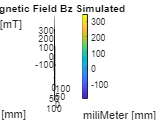


%Bzの表示%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%3D分布
surf(Ncxx*1000,Ncyy*1000,Bz*1000)
set(gca,'YDir','reverse')
b=(["Magnetic Field Bz Simulated"]);
title(b)
zlabel('miliTesla [mT]', 'FontSize',10) 
xlabel('miliMeter [mm]', 'FontSize',10) 
ylabel('miliMeter [mm]', 'FontSize',10)
colorbar

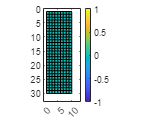


%2D分布
surf(Bsimz)
set(gca,'YDir','reverse')
colorbar
axis equal
grid off
box on
xlim([0 nxmag+2])
ylim([0 nymag+2])
xticks(0:5:nxmag+1)
yticks(0:5:nymag+1)
view([0 90.0])

## rerun it

Bm=Bsim;
[U,S,V] = svd(A)            %特異値分解

U =    -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000
   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0

S =     0.6807         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    0.6807         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0     

V =    -0.0000    0.0000   -0.0001    0.0000   -0.0001    0.0000   -0.0001    0.0001   -0.0000    0.0002   -0.0001    0.0000   -0.0000    0.0006   -0.0003    0.0013   -0.0005    0.0002   -0.0021    0.0018   -0.0004    0.0001    0.0049   -0.0005   -0.0019    0.0014    0.0051   -0.0060    0.0011    0.0008   -0.0111    0.0037    0.0005    0.0029    0.0151   -0.0013    0.0093   -0.0024    0.0026   -0.0007    0.0184   -0.0036    0.0054   -0.0057    0.0093   -0.0029    0.0143   -0.0182    0.0046   -0.0019
   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001    0.0001   -0.0001   -0.0002    0.0002   -0.0002    0.0001   -0.0000    0.0007   -0.0007    0.0013   -0.0005    0.0003   -0.0028    0.0010   -0.0004    0.0002    0.0047    0.0019   -0.0010    0.0025    0.0012   -0.0080    0.0011    0.0002   -0.0114   -0.0033    0.0020    0.0026    0.0115   -0.0099    0.0090    0.0040    0.0021    0.0009    0.0170    0.0087    0.0011   -0.0077    0.0112    0.0008    0.0220   -0.0044    0.0006   -0

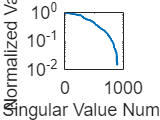

Ut=U';                      %Uの転置行列
invA1=zeros(size(S'));      %最終的な擬似逆行列
invAa=zeros(size(S'));      %1モード（1特異値）あたりの逆行列
M1=invA1*Bm;                %打ち切り判定用推定電流密度分布
adnum=0;                    %加算回数

S1=diag(S);
Snor=S1/max(S1);
p1=1:3*Ncmag;
ln=semilogy(p1,Snor,'LineWidth',2);
ax1=gca;
ax1.YAxis.Exponent = 0;
ax1.YAxis.TickLabelFormat = '%.0f';
xlabel('Singular Value Number') 
ylabel('Normalized Value')
fontsize(16,"points")




% Snor1=Snor(1:Nn*3,1);
% p2=1:Nn*3;
% ln=semilogy(p2,Snor1,'LineWidth',2);
%}
%逆行列を求めて加算invA=Σv*ut/λ
xx=1;
for aa=1:3*Ncmag
    
    invAa=(V(:,aa)*Ut(aa,:))/S(aa,aa);  %v*ut/λ
    M1=invA1*Bm;
    Smud=Snor(aa,:);%打ち切りの判定%%%%%%%%%%%%%%%%%%%%%%%  
    sss(xx)=Smud;
    xx=xx+1;
        if  Smud>=En%正規化した特異値を参照した打ち切り判定
           
            invA1=invA1+invAa;            %加算していく
            adnum=adnum+1;                %加算回数も増加

        else 
           break
        end
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
end

%計算結果確認用
invA1

invA1 =     0.0005    0.0002    0.0001    0.0006    0.0002    0.0001    0.0006    0.0003    0.0001    0.0007    0.0003    0.0001    0.0008    0.0004    0.0001    0.0008    0.0005    0.0001    0.0009    0.0006    0.0001    0.0010    0.0007    0.0001    0.0011    0.0009    0.0001    0.0012    0.0011    0.0001    0.0013    0.0013    0.0002    0.0014    0.0016    0.0002    0.0014    0.0020    0.0002    0.0014    0.0024    0.0002    0.0013    0.0028    0.0002    0.0012    0.0032    0.0002    0.0009    0.0036
    0.0005    0.0001    0.0001    0.0006    0.0002    0.0001    0.0007    0.0002    0.0001    0.0007    0.0003    0.0001    0.0008    0.0004    0.0001    0.0009    0.0005    0.0001    0.0010    0.0006    0.0001    0.0011    0.0007    0.0001    0.0012    0.0009    0.0002    0.0013    0.0011    0.0002    0.0014    0.0013    0.0002    0.0015    0.0016    0.0002    0.0016    0.0020    0.0002    0.0016    0.0024    0.0002    0.0015    0.0028    0.0002    0.0014    0.0032    0.0003    0.0011 

adnum

adnum = 900



%電流密度分布を逆計算

M=invA1*Bm

M =    -0.0000
   -0.0000
    1.0000
   -0.0000
    0.0000
    1.0000
    0.0000
    0.0000
    1.0000
    0.0000


MをMx,My,Mzの分布に変換（特に設定する値なし）

Mx=zeros(nymag-1,nxmag-1);    %x方向電流密度
My=zeros(nymag-1,nxmag-1);    %y方向
Mz=zeros(nymag-1,nxmag-1);    %z方向
Mabs=zeros(nymag-1,nxmag-1);  %大きさ
mmx=1;mmy=1;            %計算用変数


for jj=1:Ncmag

    if mmx < nxmag-1
        Mx(mmy,mmx)=M(3*(jj)-2);
        My(mmy,mmx)=M(3*(jj)-1);
        Mz(mmy,mmx)=M(3*(jj));
        Mabs(mmy,mmx)=sqrt(((M(3*(jj)-2))^2)+((M(3*(jj)-1))^2)+((M(3*(jj))^2)));
        mmx=mmx+1;
        
    elseif mmx==nxmag-1
        Mx(mmy,mmx)=M(3*(jj)-2);
        My(mmy,mmx)=M(3*(jj)-1);
        Mz(mmy,mmx)=M(3*(jj));
        Mabs(mmy,mmx)=sqrt(((M(3*(jj)-2))^2)+((M(3*(jj)-1))^2)+((M(3*(jj))^2)));
          mmx=1;
       mmy=mmy+1;
    end
end

Mx

Mx = 1.0e-13 *

   -0.0133   -0.0140    0.0069    0.0411    0.0761    0.0386   -0.0328   -0.0660   -0.0594   -0.0150
    0.0207    0.0661    0.0912    0.1051    0.1241    0.1699    0.1844    0.1303    0.0596    0.0043
   -0.0177   -0.0178   -0.0190   -0.0116   -0.0439   -0.0402   -0.0432    0.0008    0.0756    0.0394
    0.0625    0.0159   -0.0085   -0.0037    0.0313    0.0481   -0.0168   -0.0782   -0.0836   -0.0266
    0.0260    0.1190    0.0605    0.0109   -0.0613   -0.0861   -0.0369   -0.0121    0.0318    0.0180
   -0.0315   -0.1288   -0.1120   -0.0696    0.0036    0.1213    0.0295    0.0136   -0.0884   -0.0701
    0.0993    0.0939    0.0675   -0.0380   -0.0380    0.0195    0.0744    0.0567    0.0773   -0.0329
   -0.0289    0.0039   -0.1018   -0.0848   -0.0060   -0.0344   -0.0477   -0.0385   -0.0326    0.0266
    0.0726    0.0549   -0.0058    0.0290    0.0783    0.0821    0.0541    0.0222    0.0074    0.0042
   -0.0502   -0.0882   -0.0658   -0.0420   -0.0091    0.0274   -0.0045   -0

My

My = 1.0e-13 *

   -0.0168    0.0110    0.0023    0.0035    0.0490   -0.0336   -0.0493   -0.0407    0.0139   -0.0292
    0.0324    0.0080   -0.0362    0.0169    0.0418   -0.0025   -0.0437   -0.0522    0.0534   -0.0276
    0.0491   -0.0455   -0.0715    0.0781    0.0055    0.0219   -0.0286   -0.0550    0.0659   -0.0043
    0.0850   -0.0715   -0.0660    0.0014    0.0756    0.0037   -0.0540   -0.0221    0.0339    0.0354
    0.0295    0.0557   -0.0593   -0.0237    0.0250    0.0484   -0.0390   -0.0110   -0.0060   -0.0043
    0.0179    0.0640   -0.1001   -0.0136   -0.0160    0.1070   -0.0574   -0.0268   -0.0115    0.0073
    0.0797    0.0491   -0.0322   -0.0581    0.0051    0.0699    0.0165   -0.0041    0.0347   -0.0806
   -0.0246    0.0754   -0.0260    0.0216   -0.0240    0.1182   -0.0104    0.0343    0.0125   -0.0692
   -0.0473    0.0960   -0.0388    0.0177   -0.0491    0.1052   -0.0288   -0.0023   -0.0277   -0.0358
    0.0140    0.0708   -0.0424   -0.0289   -0.0021    0.1193   -0.0496   -0

Mz

Mz =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.

Mabs

Mabs =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    

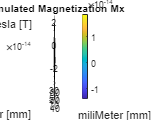

%結果のグラフ表示%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


surf(Ncxmag*1000,Ncymag*1000,Mx)
set(gca,'YDir','reverse')
b=(["Simulated Magnetization Mx"]);
%b=(["Simulated Magnetization Mx En="+En]);
title(b)
zlabel('Tesla [T]', 'FontSize',10) 
xlabel('miliMeter [mm]', 'FontSize',10) 
ylabel('miliMeter [mm]', 'FontSize',10)
colorbar

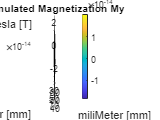



surf(Ncxmag*1000,Ncymag*1000,My)
set(gca,'YDir','reverse')
b=(["Simulated Magnetization My"]);
%b=(["Simulated Magnetization My En="+En]);
title(b)
zlabel('Tesla [T]', 'FontSize',10) 
xlabel('miliMeter [mm]', 'FontSize',10) 
ylabel('miliMeter [mm]', 'FontSize',10)
colorbar

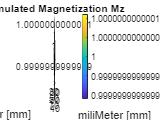



surf(Ncxmag*1000,Ncymag*1000,Mz)
set(gca,'YDir','reverse')
b=(["Simulated Magnetization Mz"]);
%b=(["Simulated Magnetization Mz En="+En]);
title(b)
zlabel('Tesla [T]', 'FontSize',10) 
xlabel('miliMeter [mm]', 'FontSize',10) 
ylabel('miliMeter [mm]', 'FontSize',10)
colorbar

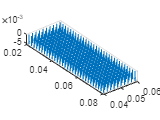





%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%磁化ベクトル分布のグラフ表示%%%%%%%%%%%%%

%MMx=abs(Mx);
%MMy=abs(My);
%MMz=abs(Mz);
%MMabs=abs(Mabs);

%Mx%%%%%%%%%%%%%%%%%%

%z方向成分(Mz)の2次元ベクトル
% quiver3(Ncxmag,Ncymag,zeros(size(Ncymag,2),size(Ncxmag,2)),zeros(size(Ncymag,2),size(Ncxmag,2)),zeros(size(Ncymag,2),size(Ncxmag,2)),-Mz,5)
quiver3(Ncxmag,Ncymag,zeros(size(Ncymag,2),size(Ncxmag,2)),Mx,My,-Mz,2)
set(gca,'YDir','reverse')
axis equal
xlim([min(Ncxmag)-Wnx/2 max(Ncxmag)+Wnx/2])
ylim([min(Ncymag)-Wny/2 max(Ncymag)+Wny/2])

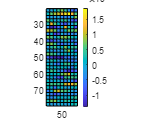

% xticks(Wnx*2:max(Ncxmag)+Wnx)
% yticks(Wny*2:max(Ncymag)+Wny)


surf(Ncxmag*1000,Ncymag*1000,Mx)
set(gca,'YDir','reverse')
axis equal
grid off
box on
% xlim([0.5 nxmag-1+0.5])
% ylim([0.5 nymag-1+0.5])
% xticks(0.5:5:nxmag)
% yticks(0.5:5:nymag+1)
colorbar
%set(colorbar,'Ticks',[-2 -1.5 -1 -0.5 0 0.5 1])
view([0 90.0])

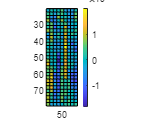



%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
 
%My%%%%%%%%%%%%%%%%%%

surf(Ncxmag*1000,Ncymag*1000,My)
set(gca,'YDir','reverse')
axis equal
grid off
box on
% xlim([0.5 nxmag-1+0.5])
% ylim([0.5 nymag-1+0.5])
% xticks(0.5:5:nxmag)
% yticks(0.5:5:nymag+1)
colorbar
%set(colorbar,'Ticks',[-2 -1.5 -1 -0.5 0 0.5 1])
view([0 90.0])

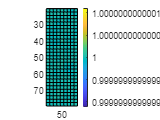


%Mz%%%%%%%%%%%%%%%%%%

surf(Ncxmag*1000,Ncymag*1000,Mz)
set(gca,'YDir','reverse')
axis equal
grid off
box on
% xlim([0.5 nxmag-1+0.5])
% ylim([0.5 nymag-1+0.5])
% xticks(0.5:5:nxmag)
% yticks(0.5:5:nymag+1)
colorbar
%set(colorbar,'Ticks',[-2 -1.5 -1 -0.5 0 0.5 1])
view([0 90.0])